# Simulation Output Structure

We load some simulation input data and run the simulation. We obtain an `output` structure in return.

jsonstruct = parseBattmoJson('Examples/Documentation/jsonfiles/explore_output_example.json');
output = runBatteryJson(jsonstruct);

Solving timestep 001/155:                      -> 1 Second, 50 Milliseconds
Solving timestep 002/155: 1 Second, 50 Milliseconds -> 2 Seconds, 100 Milliseconds
Solving timestep 003/155: 2 Seconds, 100 Milliseconds -> 4 Seconds, 200 Milliseconds
Solving timestep 004/155: 4 Seconds, 200 Milliseconds -> 8 Seconds, 400 Milliseconds
Solving timestep 005/155: 8 Seconds, 400 Milliseconds -> 16 Seconds, 800 Milliseconds
Solving timestep 006/155: 16 Seconds, 800 Milliseconds -> 33 Seconds, 600 Milliseconds
Solving timestep 007/155: 33 Seconds, 600 Milliseconds -> 67 Seconds, 200 Milliseconds
Solving timestep 008/155: 67 Seconds, 200 Milliseconds -> 100 Seconds, 800 Milliseconds
Solving timestep 009/155: 100 Seconds, 800 Milliseconds -> 134 Seconds, 400 Milliseconds
Solving timestep 010/155: 134 Seconds, 400 Milliseconds -> 168 Seconds
Solving timestep 011/155: 168 Seconds          -> 201 Seconds, 599 Milliseconds
Solving timestep 012/155: 201 Seconds, 599 Milliseconds -> 235 Seconds, 199 Millise

## Output structure overview

The output structure contains the results of the simulation, the simulation model and the simulation setup. We have in particular the following

- `output.model` : The simulation model

- `output.simsetup` : The simulation setup

- `output.jsonstruct` : The json input file

- `output.time` : Time structure of the results

- `output.E` : Voltage for each time step

- `output.I` : Current for each time step

- `output.states` : The states structure with the internal state of the battery for each time step

## Current and Voltage

The readily available results are the current and voltage with the corresponding time structure

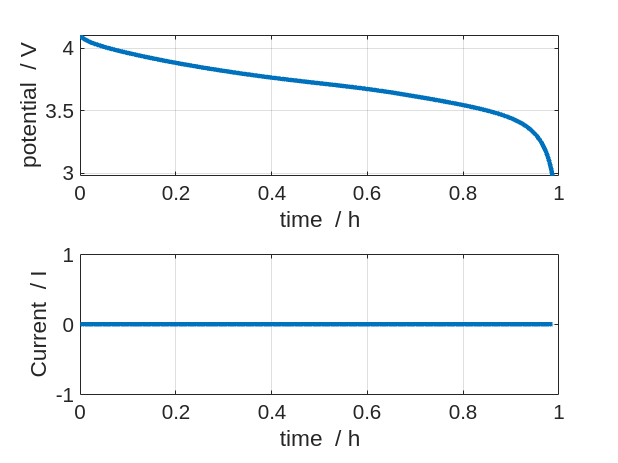

time = output.time;
E    = output.E;
I    = output.I;

figure
subplot(2,1,1)
plot(time/hour, E);
grid on
xlabel 'time  / h';
ylabel 'potential  / V';

subplot(2,1,2)
plot(time/hour, I);
grid on
xlabel 'time  / h';
ylabel 'Current  / I';

## Simulation Model

The simulation model is an output of the simulation.

model = output.model;

We can use it to plot the battery model, using the dedicated function `plotBatteryGrid`.

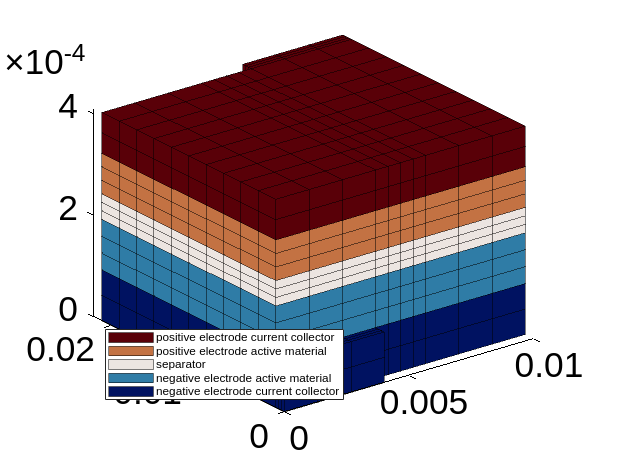

plotBatteryGrid(model);

## Battery States

The `states` give us insight into the internal state of the battery for each time step.

states = output.states;

The states are stored in a cell array. The index is the same as the time output. For a given state, the data is stored following the same architecture as the overall battery model, see [here](https://battmo.org/BattMo/architecture.html)

Let us consider the state computed at the last time step.

state = states{end}

We obtain the following variable, which are (except time and control type) the *state* or *primary* variables. They correspond to the unknowns in the modeling equations we solve. It is possible to recover also the intermediate variables as illustrated below.

- `state.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface`

- `state.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.c`

- `state.NegativeElectrode.Coating.phi`

- `state.NegativeElectrode.CurrentCollector.phi`

- `state.PositiveElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface`

- `state.PositiveElectrode.Coating.ActiveMaterial.SolidDiffusion.c`

- `state.PositiveElectrode.Coating.phi`

- `state.PositiveElectrode.CurrentCollector.scaledDeltaPhi`

- `state.Electrolyte.phi`

- `state.Electrolyte.c`

- `state.ThermalModel.T`

- `state.Control.E`

- `state.Control.I`

- `state.Control.ctrlType`

- `state.time`

Let us plot the concentration in the electrolyte. The units are always defaulted to SI units. Note also the difference of scale for the different spatial directions.

figure
plotCellData(model.Electrolyte.grid, state.Electrolyte.c);
colorbar
view([50, 40]);

## Simulation Setup

The simulation setup contains all the information to re-run a simulation. It means the model, of course, but also the initial state, the schedule (time stepping choices) and the solver parameters.

simsetup = output.simsetup();
states = simsetup.run()

## Json Input

The `jsonstruct` that is returned in the output is the same as the one we sent as input but it is augmented with all the ***default values***

## full set of state variables

In the simulation, intermediate variables are computed to assemble the equations. They can be relevant to explore your solution. They are not included by default because they require extra time to be computed. If you are interested in those, you can add the following entry in your json input structure

jsonstruct.Output.includeIntermediateVariables = true;
output = runBatteryJson(jsonstruct);

It is also possible to do the same *manually* after the simulation

for istate = 1 : numel(states)
    states{istate} = model.addVariables(states{istate});
end

For example, for the negative electrode interface, we get the following variables, among which the OCP and the intercalation flux, which is the reaction rate of Lithium intercalation (mol/m^2/s).

state = states{end};
disp(state.NegativeElectrode.Coating.ActiveMaterial.Interface)